sentFile = ["1_sent.dat"
    "1_sent_b.dat"
    "2_rx_sent.dat"
    ];

sent_cnt = length(sentFile);

recvFile = ["1_recv.dat"
    "1_recv_b.dat"
    "2_rx_recv.dat"
    ];
    
recv_cnt = length(recvFile);

for cnt = 1:1:sent_cnt
    csvread(recvFile(cnt))
    sent_data(cnt)= {csvread(sentFile(cnt))};
    recv_data(cnt) = {csvread(recvFile(cnt))};
end

ans =      2    16   210
     2    16   210
     2    16   210
     2    15   209
     2    13   210
     3    15   210
     6    18   210
     8    15   209
     8    13   209
     9    14   210


ans =     15    16   210
    15    14   210
    15    14   211
    15    17   210
    15    15   210
    15    14   210
    15    16   211
    15    14   211
    15    16   210
    15    16   210


ans =     15    16   182
    15    17   182
    15    17   182
    15    16   182
    15    15   181
    15    16   182
    15     7   190
    15    15   182
    15    15   182
    15    17   182



sent_array = cell2mat(sent_data);

recv_array = [];
for cnt = 1:1:recv_cnt
    temp_data =cell2mat(recv_data(cnt));
    temp_data = temp_data(1:757,:);
    recv_array = [recv_array temp_data];
end


nretx = [];
result = [];
delay = [];
diversity = [];
snr= [] ;
rssi = [];

for cnt = 1:1:sent_cnt
    nretx = [nretx sent_array(:,1 + 3*(cnt-1))];
    result = [result sent_array(:,2 + 3*(cnt-1))];
    delay = [delay sent_array(:,3*cnt)];
    
    diversity = [diversity recv_array(:,1 + 3*(cnt -1))];
    snr = [snr recv_array(:,2 + 3*(cnt -1))];
    rssi = [rssi recv_array(:,3*cnt)];
end

result_mean = [];
for cnt = 1:1:sent_cnt
    result_mean = [result_mean mean(result(:,cnt))];
end

result_mean

result_mean =     0.9730    1.0000    0.1260


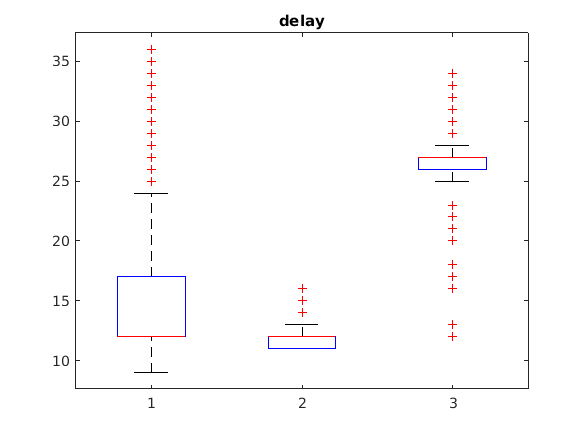



boxplot(delay)
title("delay")

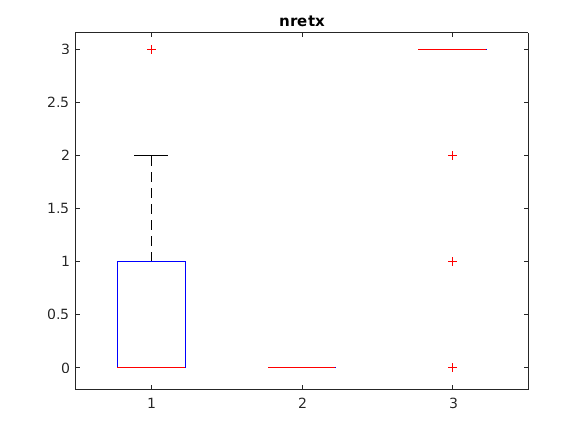

boxplot(nretx)
title("nretx")

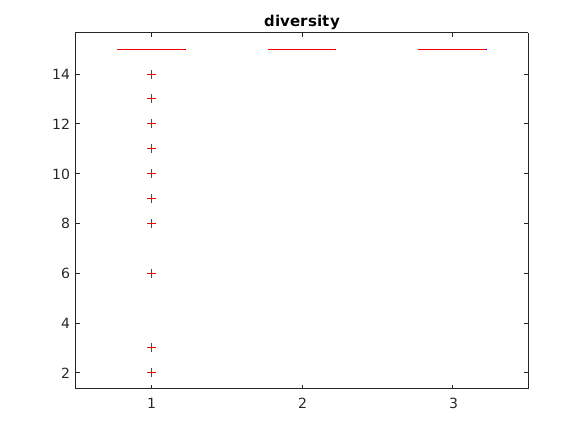

boxplot(diversity)
title("diversity")

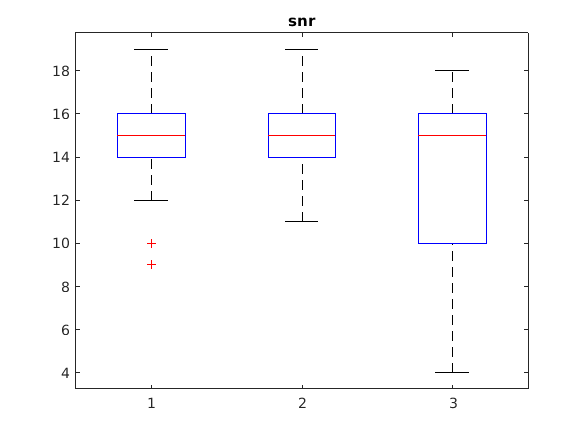

boxplot(snr)
title("snr")

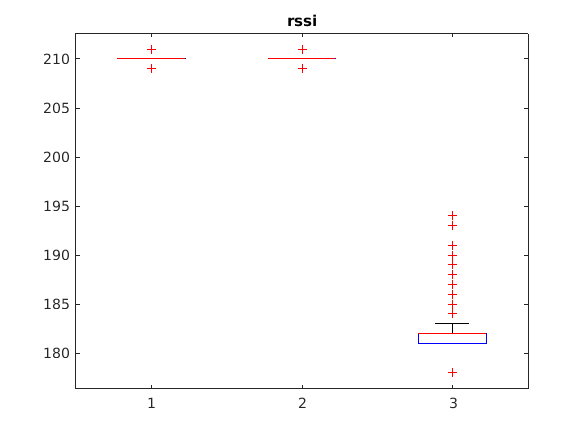

boxplot(rssi)
title("rssi")